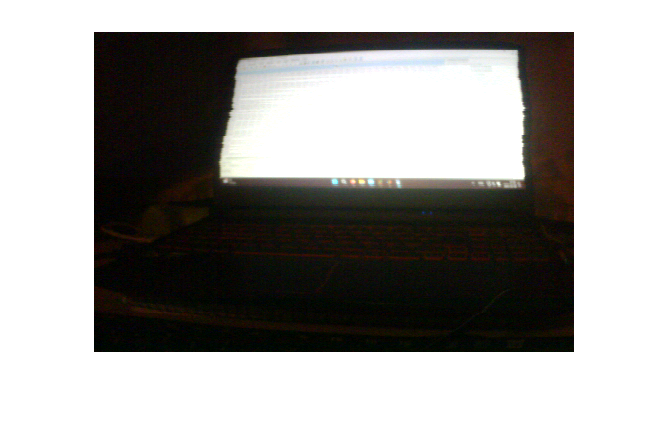

fileID = fopen('image.txt','r');
formatSpec = '%d,';
txt = fscanf(fileID,formatSpec); %153600
txt_data = reshape(txt, [480, 320]);
txt_data = flipdim(txt_data, 2);

imgR = uint8((255/31).*bitshift(bitand(txt_data, 63488), -11));  % Red component
imgG = uint8((255/63).*bitshift(bitand(txt_data, 2016), -5));    % Green component
imgB = uint8((255/31).*bitand(txt_data, 31));                    % Blue component

imgRGB = cat(3, imgR, imgG, imgB);  % Concatenate along the third dimension
imgRGB = imrotate(imgRGB, -90);
imwrite(imgRGB, 'myImage.bmp');     % Output the image to a file
imshow(imgRGB)

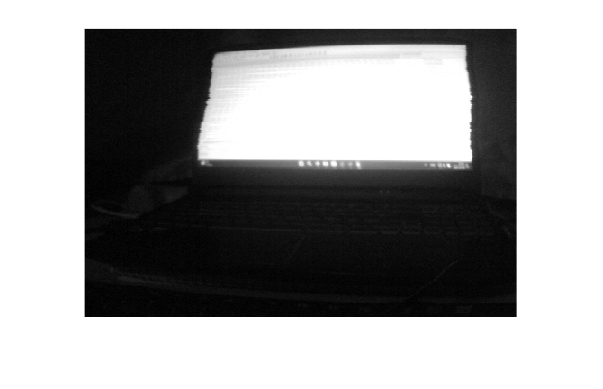

imgGray = rgb2gray(imgRGB);
BW1 = edge(imgGray,'Canny');
BW2 = edge(imgGray,'Prewitt');
BW3 = edge(imgGray,'Sobel');
imshow(imgGray)

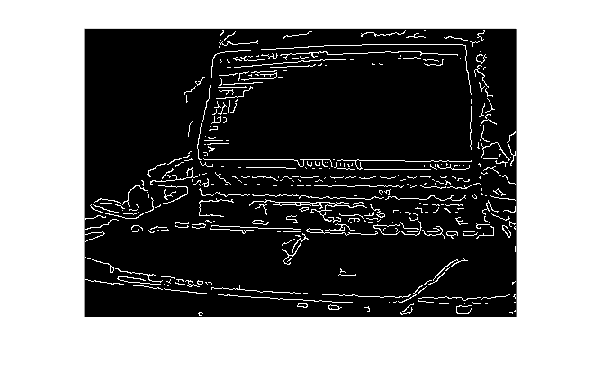

imshow(BW1)

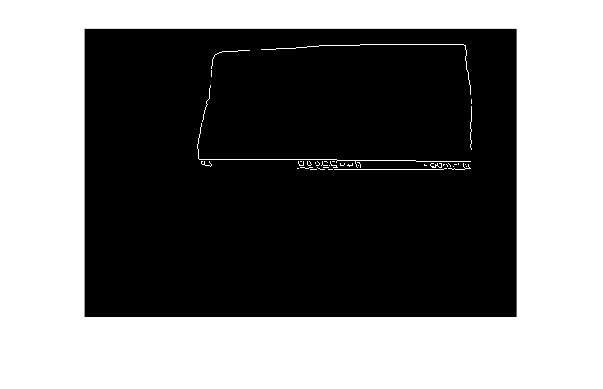

imshow(BW2)

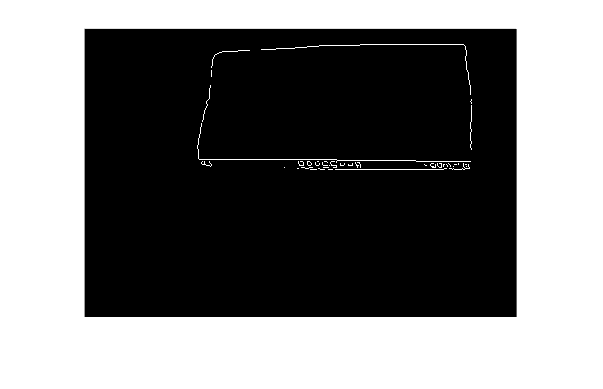

imshow(BW3)

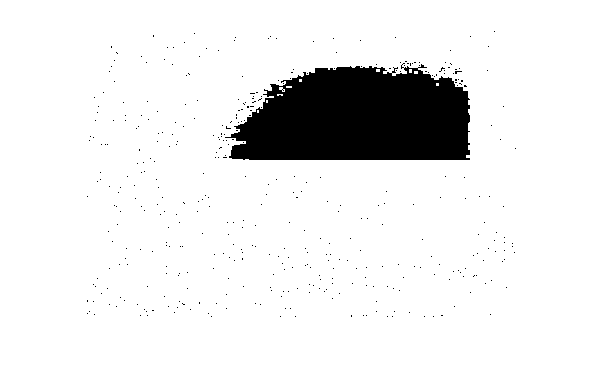

Gx = [-1, 0, 1; -2, 0, 2; -1, 0, 1];
Gy = [1, 2, 1; 0, 0, 0; -1, -2, -1];


%Cgx = conv2(Gx, Gy,imgGray);
Cgx = conv2(Gx, imgGray);
Cgy = conv2(Gy, imgGray);
G = abs(Cgx) + abs(Cgy);

imshow(G)

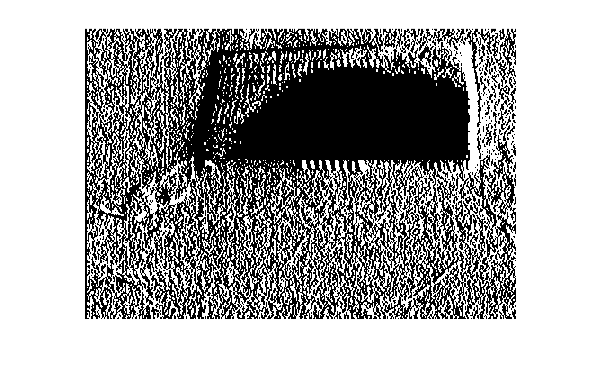

imshow(Cgx)

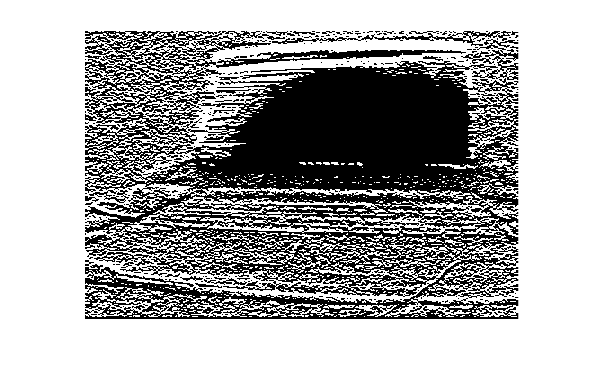

imshow(Cgy)

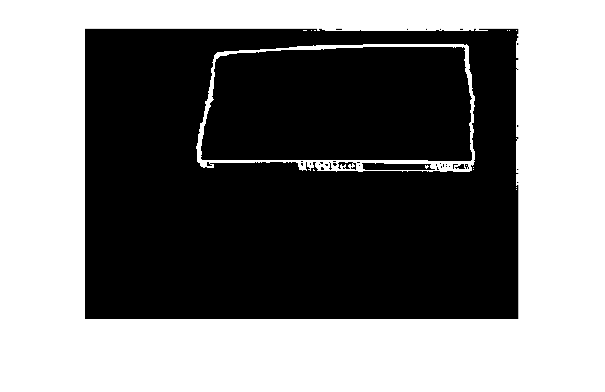

threshold = 125;
edgeImage = uint8((G > threshold) * 255);
imshow(edgeImage)